**Федеральное агентство железнодорожного транспорта**

Федеральное государственное бюджетное образовательное учреждение

высшего образования

«**Петербургский** **государственный университет путей сообщения Императора Александра ****I****»**

**(ФГБОУ ВО ПГУПС)**

­­­­­­­­­­­­––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––

Факультет «Транспортные и энергетические системы» 

Кафедра «Электрическая тяга»

**ОТЧЁТ**

**по лабораторной работе №3**

**«**Исследование трехфазного мостового управляемого выпрямителя**»**

**Вариант №4**

Выполнили:

студенты гр. ПС-003 

Дулепов И.Г.

Минина А.С.

Проверил:

Сычугов А.Н.

Санкт-Петербург

2024

**1. Цель работы - **Исследование методом компьютерного моделирования трехфазного двухполупериодного (мостового) управляемого выпрямителя при работе на  активно-индуктивную нагрузку.

**2. Карткие теоретические сведения:**

Трехфазные управляемые выпрямители строятся по схемам с  однополупериодным выпрямлением и двухполупериодным выпрямлением  (мостовые). Трехфазная мостовая схема получила преимущественное  применение при построении управляемых выпрямителей трехфазного тока. Трехфазный мостовой управляемый выпрямитель применяется для  питания обмоток возбуждения тягового электродвигателя в режиме  электрического торможения. Принципиальная схема САУТ приведена на рисунке 1. 

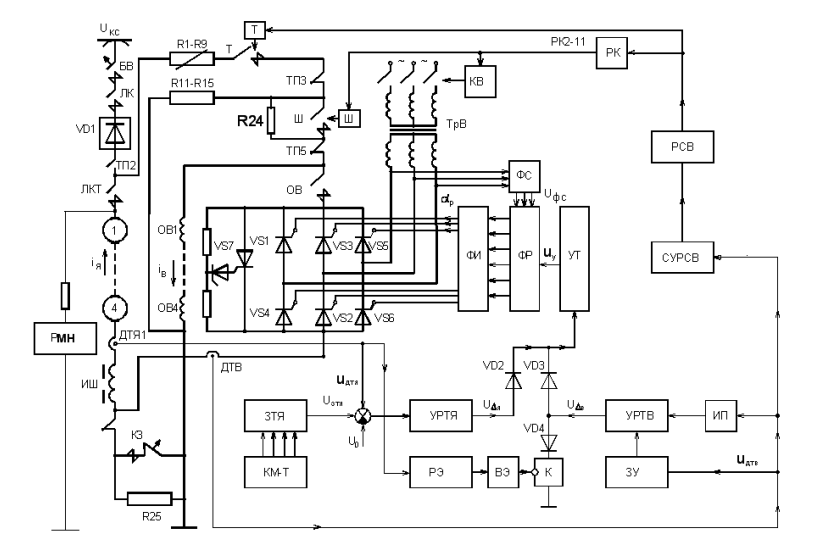

Рисунок 1. Функциональная схема САУТ электропоездов ЭР2Т, ЭТ2 

Исполнительное устройство состоит из трехфазного тиристорного  моста VS1–VS6 с симметричным управлением, питаемого от трехфазного  трансформатора возбуждения (Тр.В) (рисунок 2).

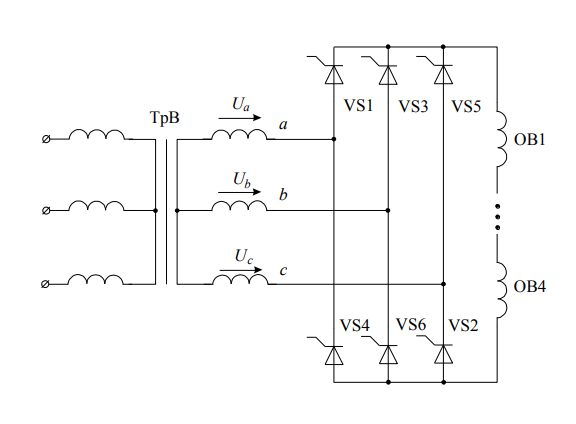

Рисунок 2. Принципиальная схема цепи возбуждения ТЭД

Тиристоры управляемого моста отпираются последовательно в  порядке увеличения их номеров со сдвигом на 60 эл. градусов (рисунок 3). К  тиристорам управляемого выпрямителя (УВ) прикладываются линейные  напряжения трансформатора возбуждения Uab, Ubc, Uca. Сигналы синхронизации Uфс отстают относительно линейных напряжений,  подводимых к УВ, на фазовый угол 30 град. , поэтому фазовый угол постоянного  сдвига выходных сигналов фазорегулятора также составляет 30 град.

Наименьший фазовый угол отпирания тиристорных плеч трехфазного  моста от начала фазы линейных напряжений составляет $\alpha$min = 60 град. Наименьший угол отпирания тиристоров моста следует считать начальным  углом регулирования моста. С учетом фазового сдвига напряжений  синхронизации относительно линейных напряжений трансформатора  возбуждения угол фазового регулирования УВ определяется следующим  выражением: $\alpha$р =$\alpha$ +($\alpha$min - 30 град.). 

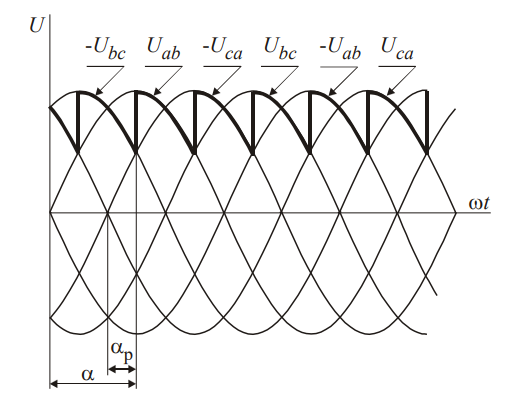

Рисунок 3. Регулировочные характеристики УВ.

**3. Схема виртуальной установки:**

Виртуальная лабораторная установка для исследований, показана на  рисунках 4-5.

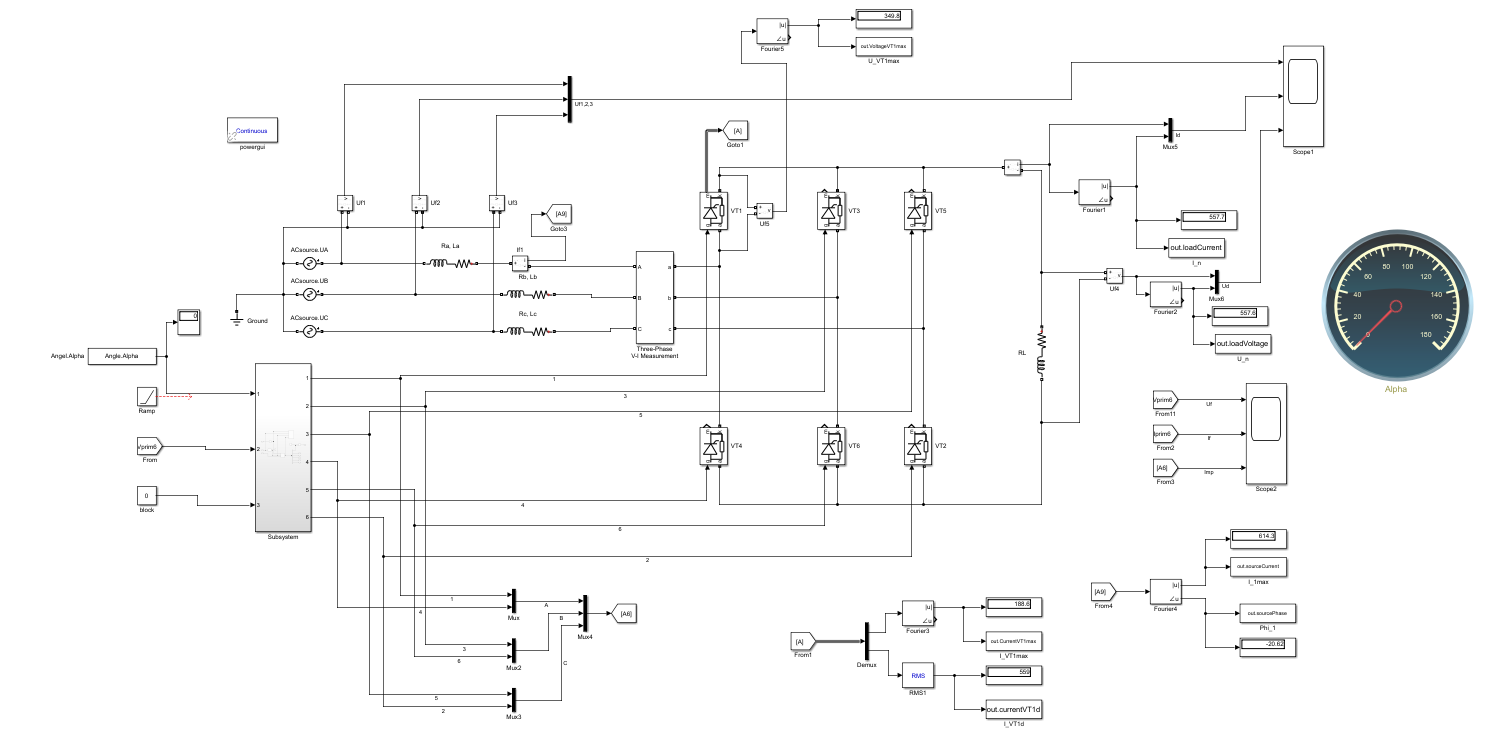

Рисунок 4. Модель трехфазного управляемого выпрямителя

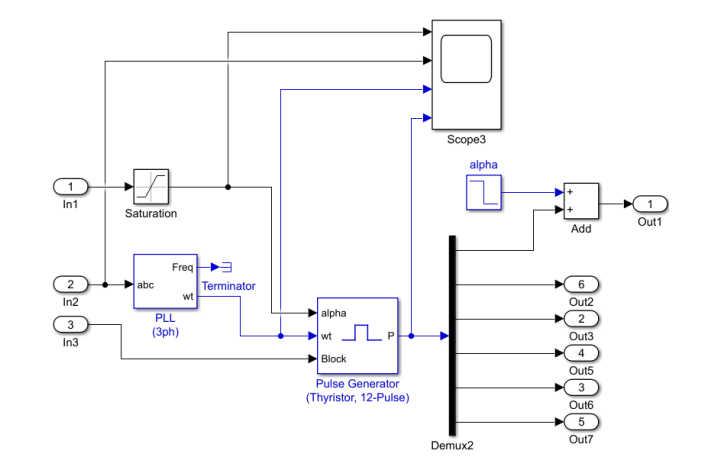

Рисунок 5. Блок управления трехфазным управляемым выпрямителем

**4. Содержание работы **

4.1. Исследование внешних и энергетических характеристик трехфазного  управляемого выпрямителя при работе на активно-индуктивную нагрузку. 

4.2. Исследование регулировочной характеристики трехфазного управляемого  выпрямителя при работе на активно-индуктивную нагрузку. 

4.3. Исследование гармонического состава тока потребления трехфазного  управляемого выпрямителя

**5. Задание исходных данных:**

Открываем файл с заданными параметрами:

open('Задание к ЛР3.txt')

Используем исходные данные, импортируемые из текстового файла задания:

C = readcell('Задание к ЛР3.txt');
ishoddan = C(4:12, 2:3);
data.Var = ishoddan{1,1};
data.U_A = ishoddan{3,2};
data.f_c = ishoddan{4,2};
data.L_T = ishoddan{5,2};
data.R_T = ishoddan{6,2};
data.U_f = ishoddan{8,2};
data.R_on = ishoddan{9,2};
data.T = table(data.Var.', data.U_A.', data.f_c.', data.L_T.', data.R_T.', data.U_f.',data.R_on.');
data.T.Properties.VariableNames = ["Вариант", "U_A, В","f_c, Гц","L_T, Гн","R_T, Ом","U_f, В","R_on, Ом"];
disp(data.T);

    Вариант    U_A, В    f_c, Гц    L_T, Гн    R_T, Ом    U_f, В    R_on, Ом
    _______    ______    _______    _______    _______    ______    ________

       4        300        200      4.8e-05     0.004      1.2       0.0025 



**Далее задаем в блоки модели Simulink:**

**Параметры блоков моделирующих трехфазный источник напряжения:**

Блоки UA; UB; UC соответственно:

В параметрах каждого блока задаем частоту, амплитуду и фазу однофазного напряжения:

ACsource.f_c = data.f_c;

Фаза А:

ACsource.U_A = data.U_A*1.41;
Phase.A = 0;

Фаза B:

ACsource.U_B = data.U_A*1.41;
Phase.B = 240;

Фаза C:

ACsource.U_C = data.U_A*1.41;
Phase.C = 120;

**Параметры блоков моделирующих сопротивление и  индуктивность источника питания, а также нагрузки:**

Блоки Ra, La; Rb, Lb; Rc, Lc; RL, соответственно:

RaLa.Res = data.R_T; %Сопротивление источников питания
RaLa.Ind = data.L_T;
RbLb.Res = data.R_T;
RbLb.Ind = data.L_T;
RcLc.Res = data.R_T;
RcLc.Ind = data.L_T;
RL.Res = 1; %Сопротивление нагрузки изменяем от 1 до 10 Ом Rn, блок RL
RL.constInd = 3;
RL.Ind = (RL.Res/ACsource.f_c)*RL.constInd; %Ln, блок RL

**Параметры блоков моделирующих тиристоры управляемого  выпрямителя:**

Блоки VT1; VT3; VT5; VT2; VT4; VT6 соответственно:

VT.Res = data.R_on; %Параметры блоков VT1-VT6
VT.U_f = data.U_f; %Параметры блоков VT1-VT6

Угол управления выпрямителем:

Angle.Alpha = 0;

**6. Таблицы опытных и расчетных данных.**

**6.1. Измерение и расчет характеристик трехфазного двухполупериодного (мостового) управляемого выпрямителя.**

Подготавливаем массивы для снятия параметров измерений в таблицу 1., (снятие внешних характеристик при изменении угла alpha и сопротивления нагрузки RL).

U_a = [];
f_c = [];
Alpha = [];
R_n = [];
L_n = []; %блок RL
I_n = [];
U_n = [];
I_1max = [];
Phi_1 = [];
I_VT1sr = [];
I_VT1d = [];
I_VT1max = [];
U_VT1max = [];
S_1 = [];
P_t = [];
P_1 = [];
P_n = [];

Открываем файл исследуемой модели:

open("lab322.slx")

При снятии внешних характеристик угол регулирования остается  неизменным, изменяются параметры Rн при значениях 1, 2, 4 и 10 Ом и  Lн  соответственно (так чтобы  оставалась неизменным постоянная времени). Внешние характеристики  снимаем для трех значений угла управления выпрямителем (α= 0°, 40°, 60°). 

Задаем шаг с которым будут изменятся значения угла регулирования и сопротивления Rн:

a = [0 40 60].'; %блок Alpha
R = [1 2 4 10].'; %блок RL
RnumStep = height(R)

RnumStep = 4

RStep=1;
Rnmax=height(R);

for A = a(1:1:end).' %end - до последнего значения в массиве a
    Angle.Alpha = A;
    Alpha(end+RStep) = Angle.Alpha;
    Alpha = repelem(a(1:1:end).',RnumStep);
            for Rn = R(1:RStep:end).' %end - до последнего значения в массиве R
            RL.Res = Rn;
            RL.Ind = (RL.Res/ACsource.f_c)*RL.constInd;
            sim('lab322.slx');
            U_a(end+1) = ACsource.U_A(end, 1);
            f_c(end+1)= ACsource.f_c(end, 1);
            R_n(end+1) = RL.Res(end, 1);
            L_n(end+1) = RL.Ind(end, 1);
            I_n(end+1) = round(max(ans.loadCurrent(end, 1)),2);
            U_n(end+1) = round(max(ans.loadVoltage(end, 1)),2);
            I_1max(end+1) = round(max(ans.sourceCurrent(end, 1)),2);
            Phi_1(end+1)= round(max(ans.sourcePhase(end, 1)),2);
            I_VT1sr(end+1) = round(mean(ans.CurrentVT1max(end, 1)),2);
            I_VT1d(end+1) = round(max(ans.currentVT1d(end, 1)),2);
            I_VT1max(end+1) = round(max(ans.CurrentVT1max(end, 1)),2);
            U_VT1max(end+1) = round(max(ans.VoltageVT1max(end, 1)),2);
            S_1(end+1) = round((((3*ACsource.U_A(end, 1)*max(ans.sourceCurrent(end, 1)))/2)*(10^-3)),1);
            Uf = data.U_f;
            Ron = data.R_on;
            P_t(end+1) =  round(Uf*max(ans.CurrentVT1max(end, 1))+Ron*(max(ans.currentVT1d(end, 1))^2),2);
            P_1(end+1) = round(((abs(3*(ACsource.U_A(end, 1)*max(ans.sourceCurrent(end, 1))/2) * (max(ans.sourcePhase(end, 1)))))*(10^-3)),2);
            P_n(end+1) = round(((max(ans.loadVoltage(end, 1))*max(ans.loadCurrent(end, 1)))*(10^-3)),2);
            end 
end

Результаты моделирования заносим в таблицу 1.

Таблица 1 – Таблица измерений и вычислений

T1 = table(U_a.',f_c.',Alpha.',R_n.', L_n.',I_n.',U_n.',I_1max.',Phi_1.',I_VT1sr.',I_VT1d.',I_VT1max.',U_VT1max.',S_1.',P_t.',P_1.',P_n.');
T1.Properties.VariableNames = ["U_a, В.","f_c, Гц.","Alpha, град.","R_n, Ом.", "L_n, Гн.","I_n, А.","U_n, В.","I_1max, А.","Phi_1, град.","I_VT1sr, А.","I_VT1d, А.","I_VT1max, А.","U_VT1max, В.","S_1, кВА.","P_t, Вт.","P_1, кВт.","P_n, кВт."];
disp(T1);

    U_a, В.    f_c, Гц.    Alpha, град.    R_n, Ом.    L_n, Гн.    I_n, А.    U_n, В.    I_1max, А.    Phi_1, град.    I_VT1sr, А.    I_VT1d, А.    I_VT1max, А.    U_VT1max, В.    S_1, кВА.    P_t, Вт.    P_1, кВт.    P_n, кВт.
    _______    ________    ____________    ________    ________    _______    _______    __________    ____________    ___________    __________    ____________    ____________    _________    ________    _________

Полную и активную мощности по первой гармонике, потребляемые выпрямителем из сети, рассчитываем по выражениям: 

где U1max и I1max амплитудные значения фазного напряжения и тока  подводимых к УВ

где 𝜑1 - угол между фазным напряжением и током подводимых к УВ. 

Мощность в нагрузке определяем по выражению: 

где UH и IH - средние значения напряжения и тока на нагрузке.

Потери в тиристоре УВ рассчитываем по выражению: 

где Uf - напряжение на p/n переходе тиристора, IVTср – среднее значение тока тиристора, IVTд – действующее значение тока тиристора. 

**6.2. Исследование регулировочной характеристики управляемого трехфазного выпрямителя:**

Исследование регулировочной характеристики управляемого трехфазного выпрямителя осуществляем при одном значении Rн. Изменение угла управления производим в диапазоне от 0  до 120 градусов с шагом 20 градусов.

RL.Res = 1;
RL.Ind = (RL.Res/ACsource.f_c)*RL.constInd;

Подготавливаем массивы для снятия параметров измерений в таблицу 2.

Alpha2 = [];
U_n2 = [];
U_n2rash = [];

Выпрямленное напряжение цепи возбуждения ТЭД рассчитывается по  формуле:

1,35 - коэффициент выпрямления трехфазной мостовой схемы;

Моделирование осуществляем при каждом значении угла управления, при этом заполняем таблицу 2.

for b = 0:20:120
    Angle.Alpha = b;
    Alpha2(end+1) = Angle.Alpha;
    sim('lab322.slx');
    U_n2(end+1)= round(max(ans.loadVoltage(end, 1)),3);
    if cos((Angle.Alpha*pi)/180)>0
    U_n2rash(end+1) = round(1.35*ACsource.U_A*cos((Angle.Alpha*pi)/180),2);
    else
    U_n2rash(end+1) = 0;
    end
end 

Заносим результаты моделирования в таблицу 2.

Таблица 2 – Измерение и расчет регулировочной характеристики.

T2 = table(Alpha2.',U_n2.',U_n2rash.');
T2.Properties.VariableNames = ["Alpha, град.","U_n, В.","U_nrash, В."];
disp(T2);

    Alpha, град.    U_n, В.    U_nrash, В.
    ____________    _______    ___________

          0         637.25       571.05   
         20         576.51       536.61   
         40         464.35       437.45   
         60         288.25       285.53   
         80         79.833        99.16   
        100          0.384            0   
        120           0.17            0   



**7. Построение нагрузочных, энергетических и регулировочных характеристик:**

**Нагрузочная характеристика:**

Нагрузочная характеристика зависимости Un = f(In) представлена на графике ниже:

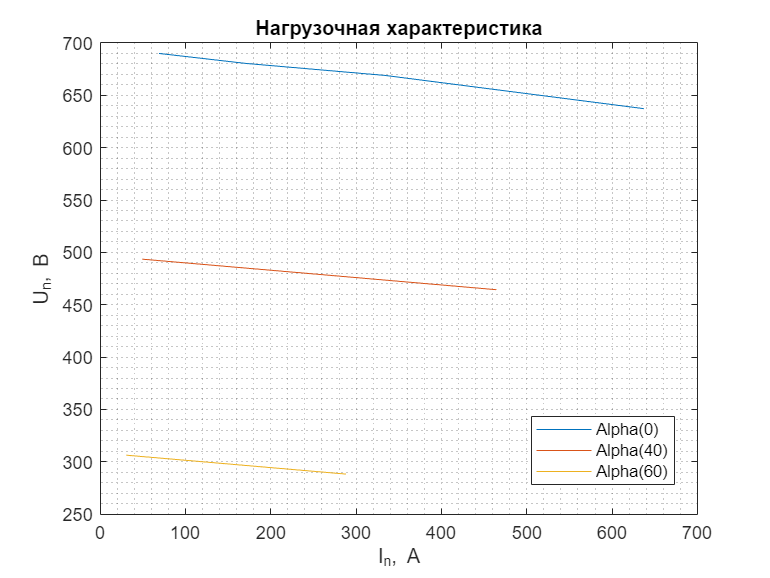

x1 = I_n(1:4).';
y1 = U_n(1:4).';
x2 = I_n(5:8).';
y2 = U_n(5:8).';
x3 = I_n(9:12).';
y3 = U_n(9:12).';
plot(x1,y1,x2,y2,x3,y3)
grid("minor");
xlabel('I_n, А');
ylabel('U_n, В');
title('Нагрузочная характеристика');
legend(["Alpha(0)","Alpha(40)","Alpha(60)"])
legend("Position",[0.69056,0.16136,0.18571,0.11905]);

**Энергетические характеристики:**

Энергетические характеристики зависимости S1 = f(Pн):

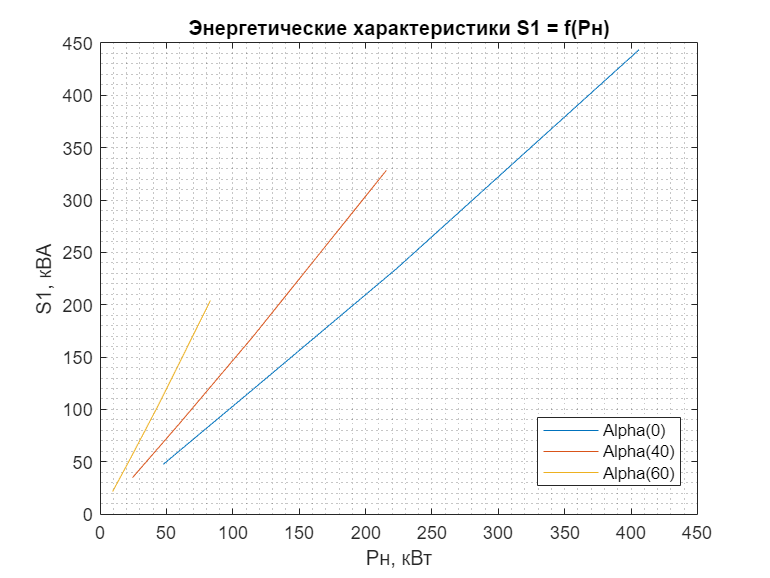

x1 = P_n(1:4).';
y1 = S_1(1:4).';
x2 = P_n(5:8).';
y2 = S_1(5:8).';
x3 = P_n(9:12).';
y3 = S_1(9:12).';
plot(x1,y1,x2,y2,x3,y3)
grid("minor");
xlabel('Pн, кВт');
ylabel('S1, кВА');
title('Энергетические характеристики S1 = f(Pн)');
legend(["Alpha(0)","Alpha(40)","Alpha(60)"])
legend("Position",[0.69836,0.15962,0.18571,0.11905]);

Энергетические характеристики зависимости P1 = f(Pн):

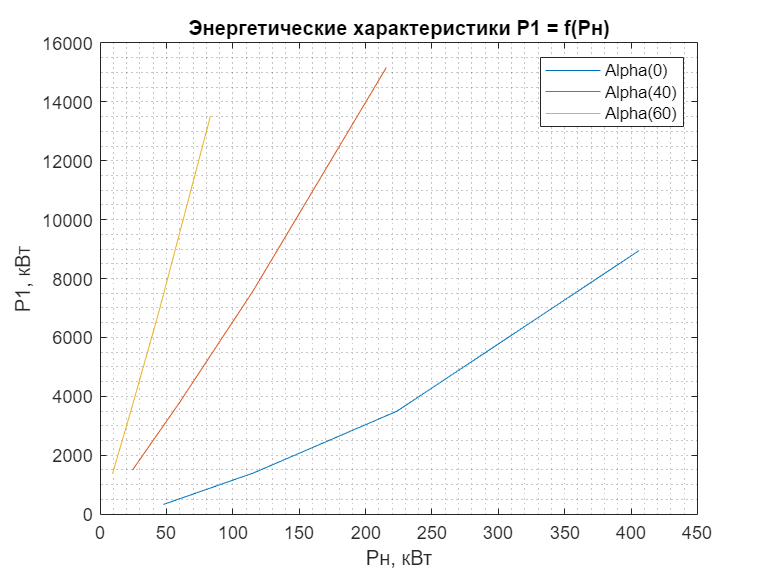

x1 = P_n(1:4).';
y1 = P_1(1:4).';
x2 = P_n(5:8).';
y2 = P_1(5:8).';
x3 = P_n(9:12).';
y3 = P_1(9:12).';
plot(x1,y1,x2,y2,x3,y3)
grid("minor");
xlabel('Pн, кВт');
ylabel('P1, кВт');
title('Энергетические характеристики P1 = f(Pн)');
legend(["Alpha(0)","Alpha(40)","Alpha(60)"])

Энергетические характеристики зависимости Pт = f(Pн):

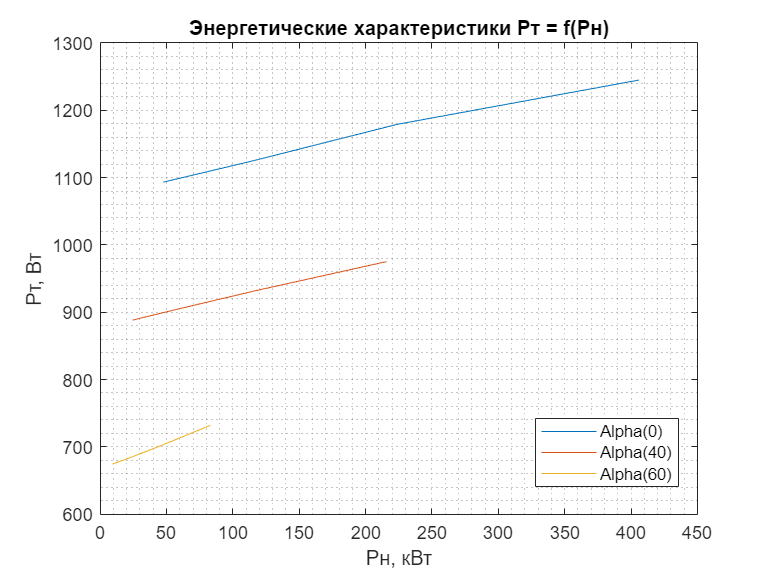

x1 = P_n(1:4).';
y1 = P_t(1:4).';
x2 = P_n(5:8).';
y2 = P_t(5:8).';
x3 = P_n(9:12).';
y3 = P_t(9:12).';
plot(x1,y1,x2,y2,x3,y3)
grid("minor");
xlabel('Pн, кВт');
ylabel('Pт, Вт');
title('Энергетические характеристики Pт = f(Pн)');
legend(["Alpha(0)","Alpha(40)","Alpha(60)"])
legend("Position",[0.69576,0.15789,0.18571,0.11905]);

Энергетические характеристики зависимости IVT1д = f(Iн):

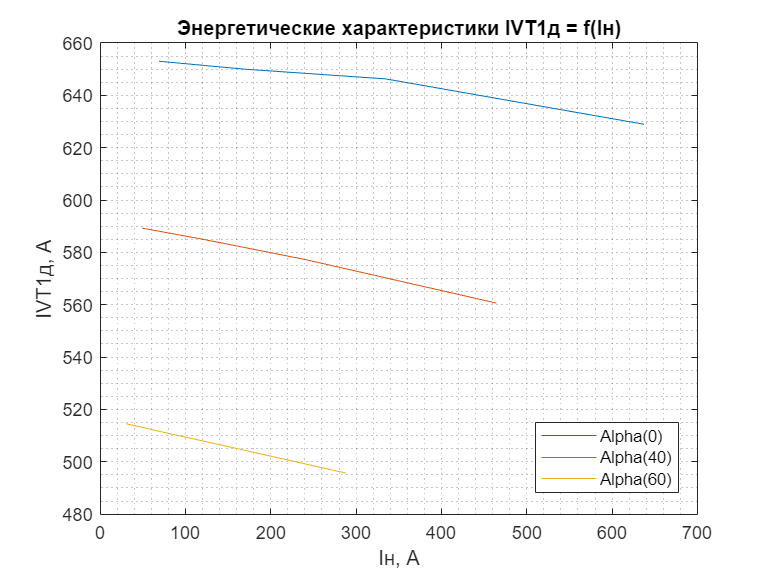

x1 = I_n(1:4).';
y1 = I_VT1d(1:4).';
x2 = I_n(5:8).';
y2 = I_VT1d(5:8).';
x3 = I_n(9:12).';
y3 = I_VT1d(9:12).';
plot(x1,y1,x2,y2,x3,y3)
grid("minor");
xlabel('Iн, А');
ylabel('IVT1д, А');
title('Энергетические характеристики IVT1д = f(Iн)');
legend(["Alpha(0)","Alpha(40)","Alpha(60)"])
legend("Position",[0.69576,0.14924,0.18571,0.11905]);

Энергетические характеристики зависимости IVTср = f(Iн):

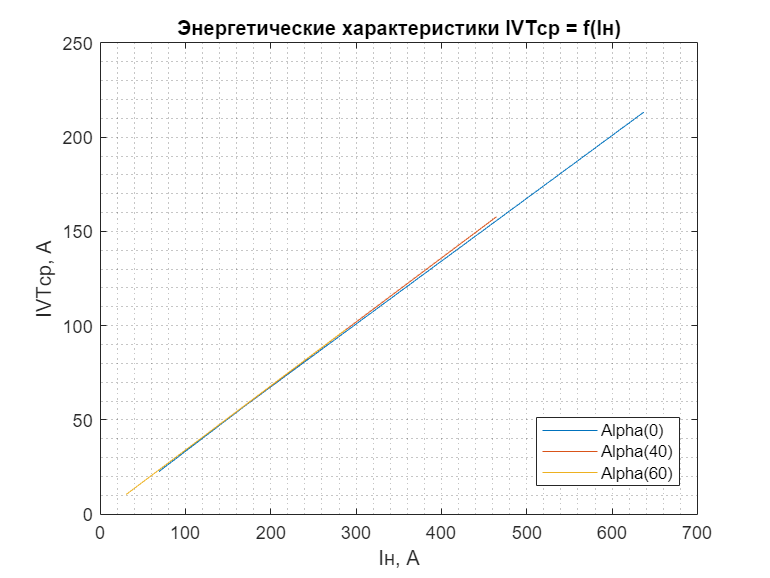

x1 = I_n(1:4).';
y1 = I_VT1sr(1:4).';
x2 = I_n(5:8).';
y2 = I_VT1sr(5:8).';
x3 = I_n(9:12).';
y3 = I_VT1sr(9:12).';
plot(x1,y1,x2,y2,x3,y3)
grid("minor");
xlabel('Iн, А');
ylabel('IVTср, А');
title('Энергетические характеристики IVTср = f(Iн)');
legend(["Alpha(0)","Alpha(40)","Alpha(60)"])
legend("Position",[0.69706,0.15962,0.18571,0.11905]);

Энергетические характеристики зависимости I1(1)max= f(Iн):

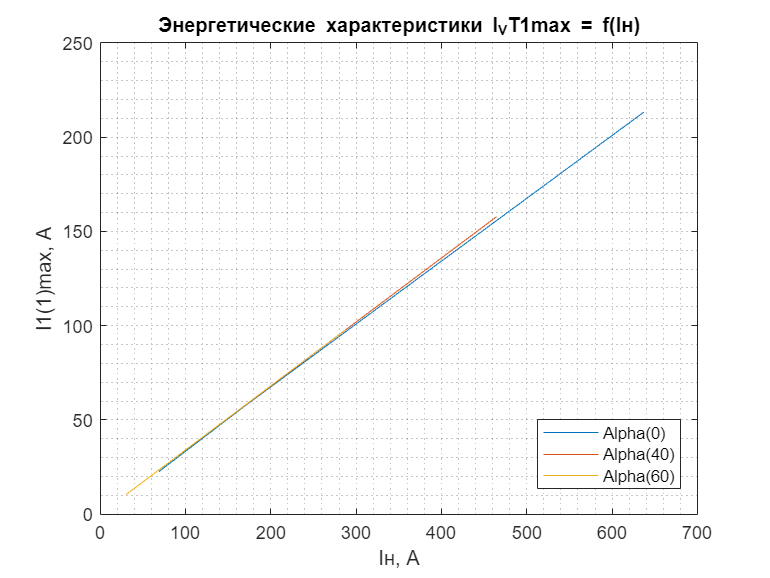

x1 = I_n(1:4).';
y1 = I_VT1max(1:4).';
x2 = I_n(5:8).';
y2 = I_VT1max(5:8).';
x3 = I_n(9:12).';
y3 = I_VT1max(9:12).';
plot(x1,y1,x2,y2,x3,y3)
grid("minor");
xlabel('Iн, А');
ylabel('I1(1)max, А');
title('Энергетические характеристики I_VT1max = f(Iн)');
legend(["Alpha(0)","Alpha(40)","Alpha(60)"])
legend("Position",[0.69835,0.15443,0.18571,0.11905]);

**Регулировочная характеристика:**

Регулировочная характеристика зависимости Uн = f(Alpha) для опытных и расчетных данных представлены на графике ниже:

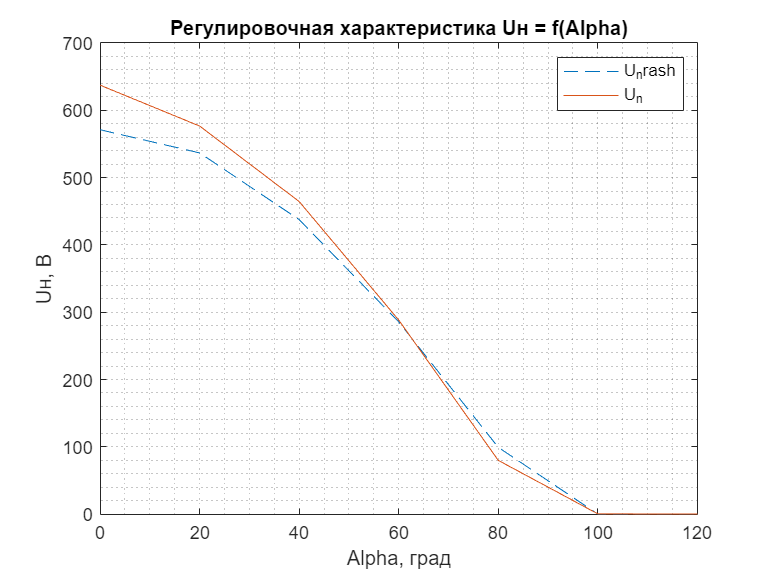

x1 = Alpha2(1:end).';
y1 = U_n2rash(1:end).';
x2 = Alpha2(1:end).';
y2 = U_n2(1:end).';
plot(x1,y1,'--',x2,y2)
grid("minor");
xlabel('Alpha, град');
ylabel('Uн, В');
title('Регулировочная характеристика Uн = f(Alpha)');
legend(["U_nrash","U_n"])

**8. Диаграммы токов и напряжений управляемого мостового  выпрямителя, а также сигналов системы управления для углов регулирования (α= 0°, 40°, 60°). **

Масштаб построения осцилограмм по горизонали:

x.min = 0.44;
x.max = 0.45;

**8.1. При угле альфа = 0 и сопротивлении нагрузки Rn = 1 Ом:**

Диаграммы блока Scope 1:

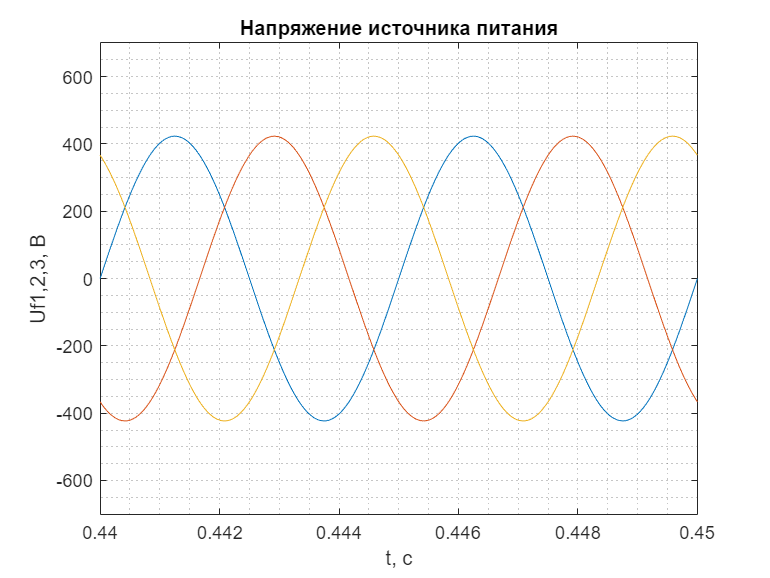

for a = 0
    Angle.Alpha = a;
    sim 'lab322.slx';
    RL.Res = 1;
    RL.Ind = RL.Res/ACsource.f_c;
end  
    plot(ans.Scope1{1}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Uf1,2,3, В');
    title('Напряжение источника питания');
    xlim([x.min x.max]);
    ylim([-700 700]);

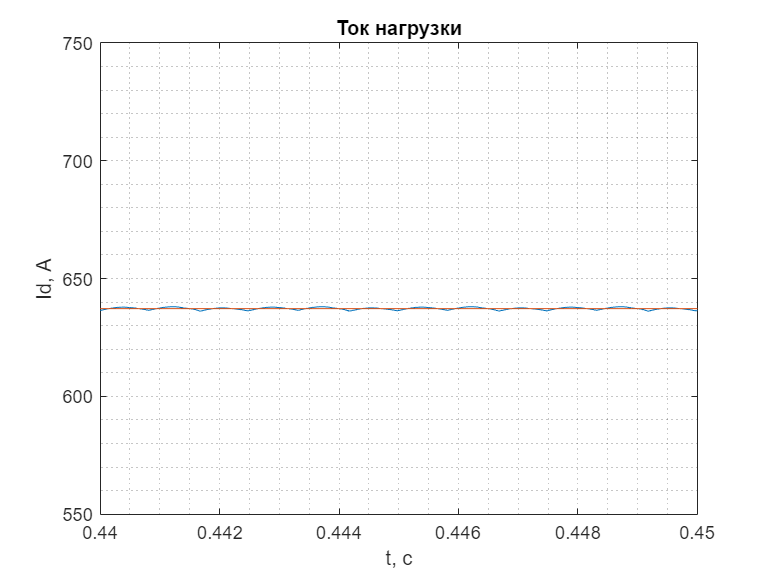

plot(ans.Scope1{2}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Id, А');
    title('Ток нагрузки');
  xlim([x.min x.max]);
  ylim([550 750]);   

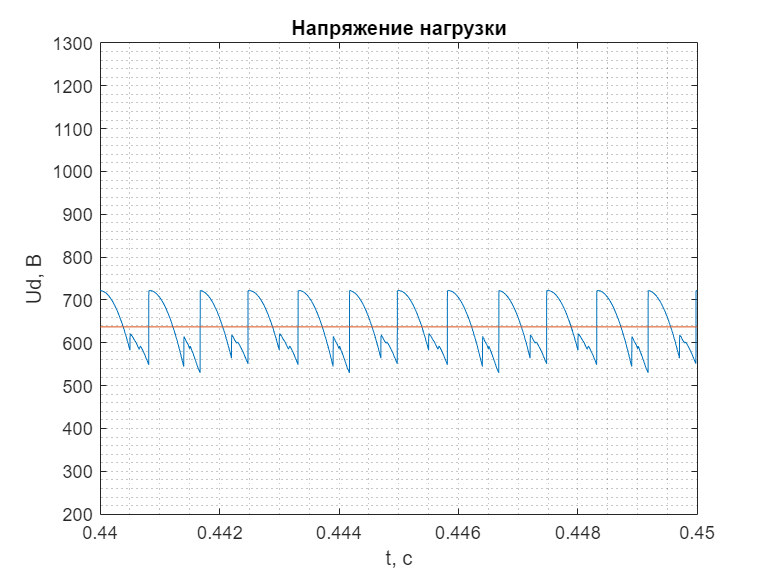

plot(ans.Scope1{3}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Ud, В');
    title('Напряжение нагрузки');
    xlim([x.min x.max]);
    ylim([200 1300]);

Диаграммы блока Scope 2:

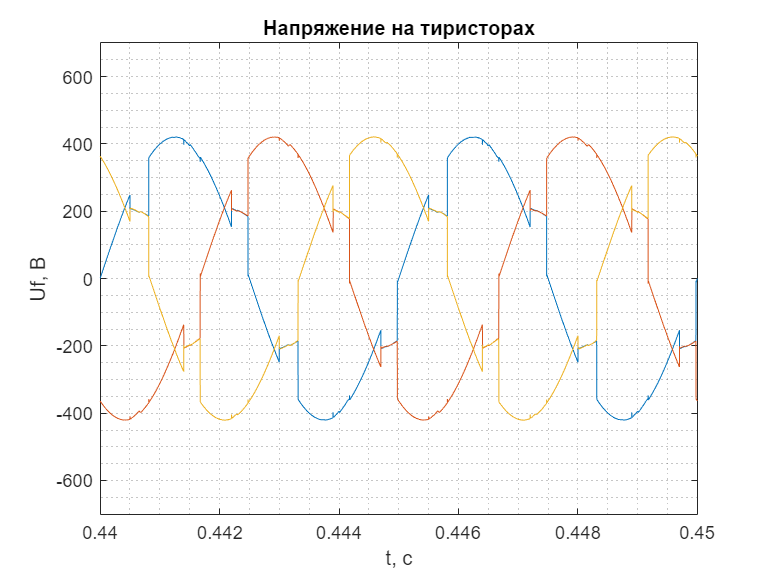

plot(ans.Scope2{1}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Uf, В');
    title('Напряжение на тиристорах');
    xlim([x.min x.max]);
    ylim([-700 700]);

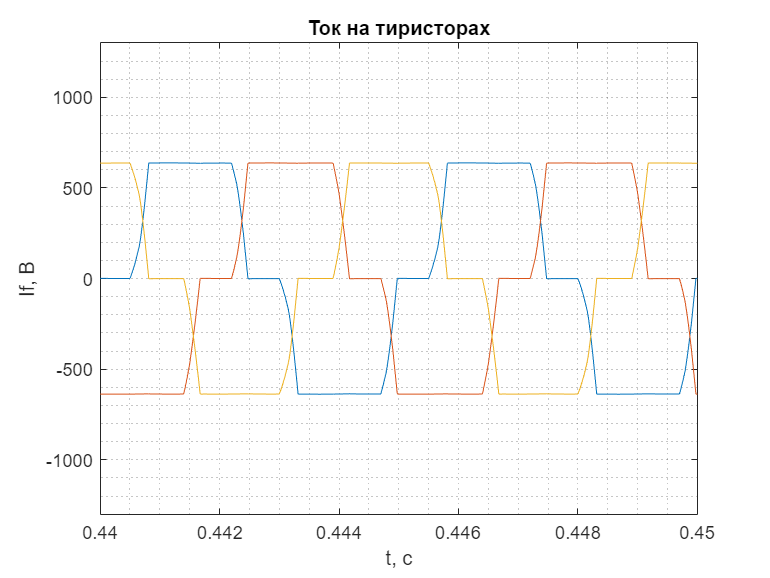

plot(ans.Scope2{2}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('If, В');
    title('Ток на тиристорах');
    xlim([x.min x.max]);
    ylim([-1300 1300]);

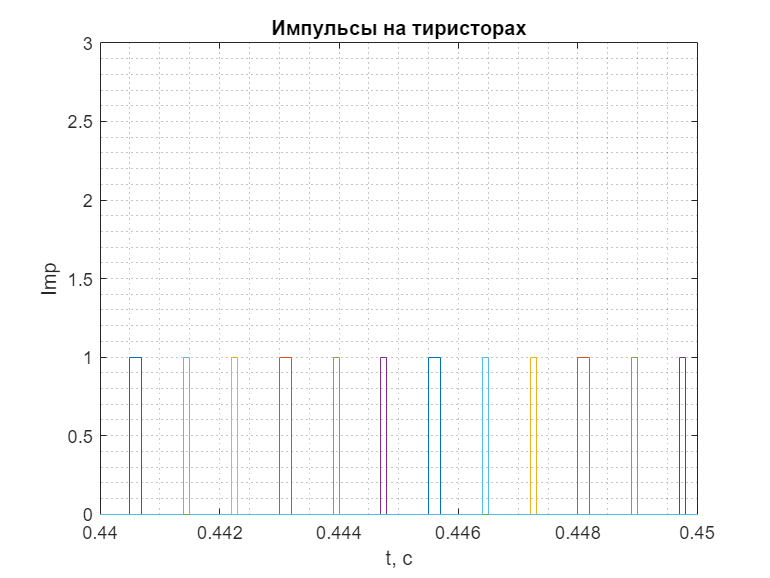

plot(ans.Scope2{3}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Imp');
    title('Импульсы на тиристорах');
    xlim([x.min x.max]);
    ylim([0 3]);

Диаграммы блока Scope 3:

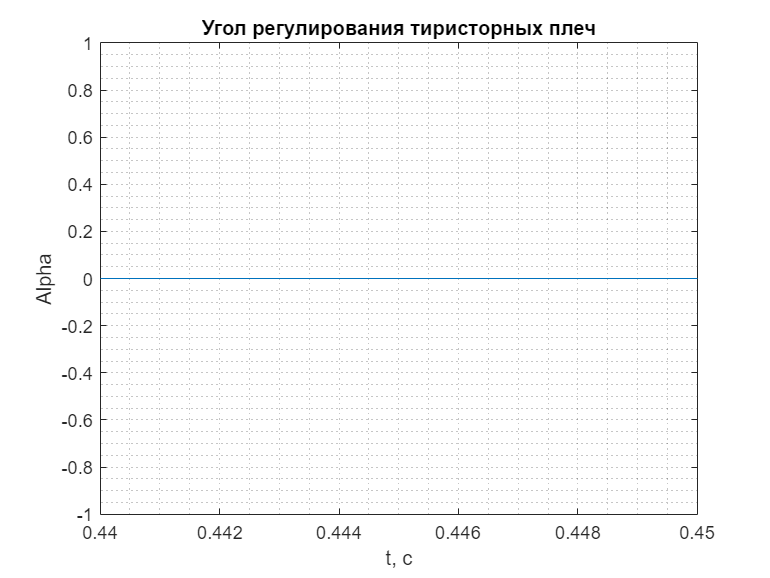

plot(ans.Scope3{1}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Alpha');
    title('Угол регулирования тиристорных плеч');
    xlim([x.min x.max]);

plot(ans.Scope3{2}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Uf, В');
    title('Напряжение на тиристорах');
    xlim([x.min x.max]);
    ylim([-700 700]);

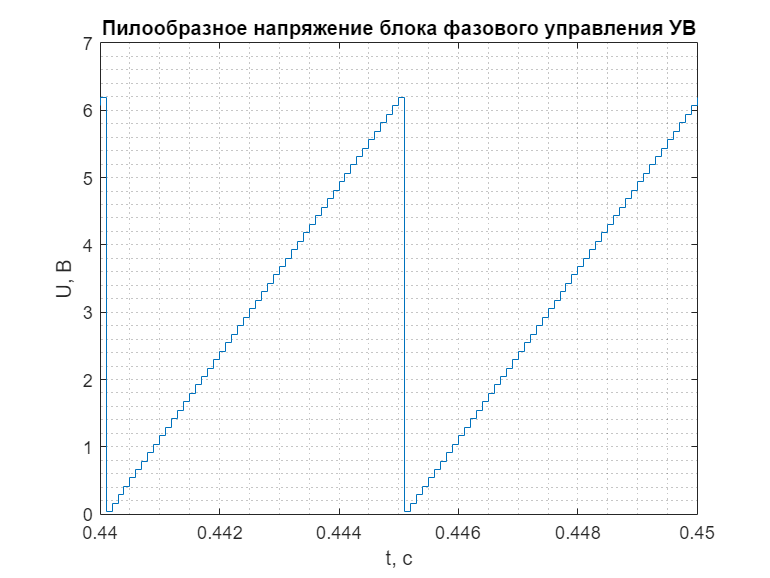

plot(ans.Scope3{3}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('U, В');
    title('Пилообразное напряжение блока фазового управления УВ');
    xlim([x.min x.max]);

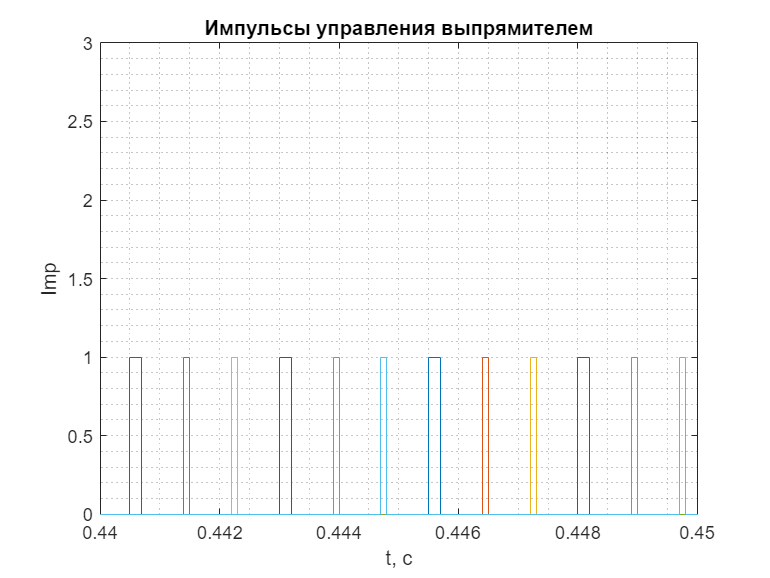

plot(ans.Scope3{4}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Imp');
    title('Импульсы управления выпрямителем');
    xlim([x.min x.max]);
    ylim([0 3]);

**8.2. При угле альфа = 40 и сопротивлении нагрузки Rn = 1 Ом:**

Диаграммы блока Scope 1:

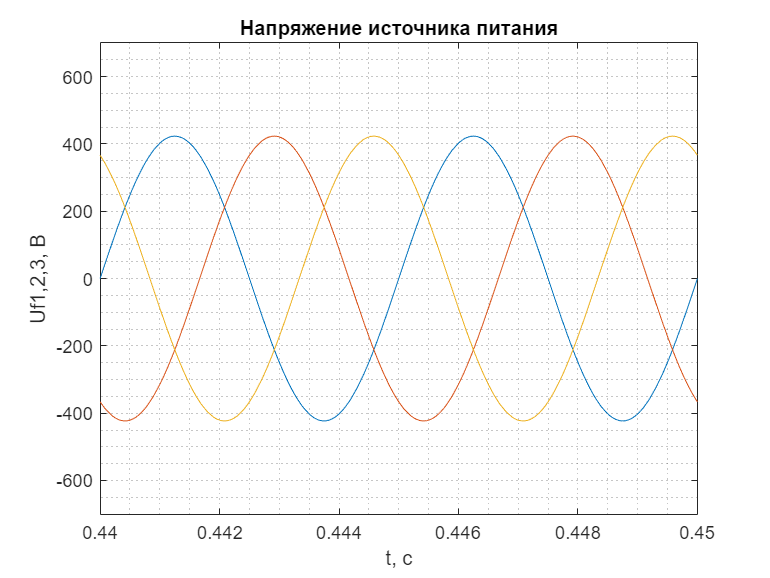

for a = 40
    Angle.Alpha = a;
    sim 'lab322.slx';
    RL.Res = 1;
    RL.Ind = RL.Res/ACsource.f_c;
end  
    plot(ans.Scope1{1}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Uf1,2,3, В');
    title('Напряжение источника питания');
    xlim([x.min x.max]);
    ylim([-700 700]);

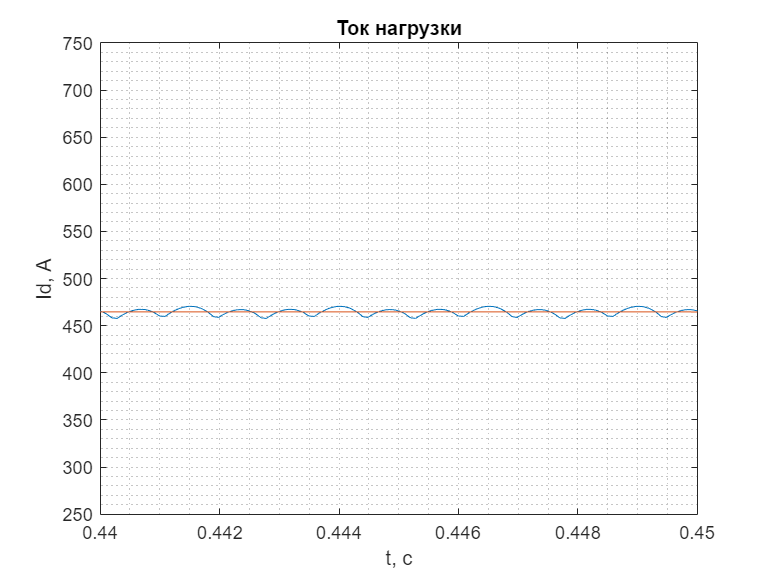

    plot(ans.Scope1{2}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Id, А');
    title('Ток нагрузки');
    xlim([x.min x.max]);
    ylim([250 750]);

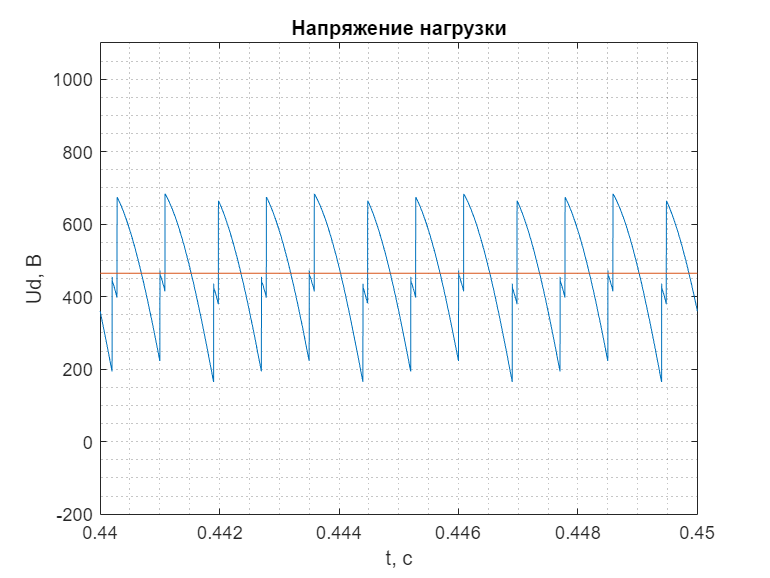

     plot(ans.Scope1{3}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Ud, В');
    title('Напряжение нагрузки');
    xlim([x.min x.max]);
    ylim([-200 1100]);

Диаграммы блока Scope 2:

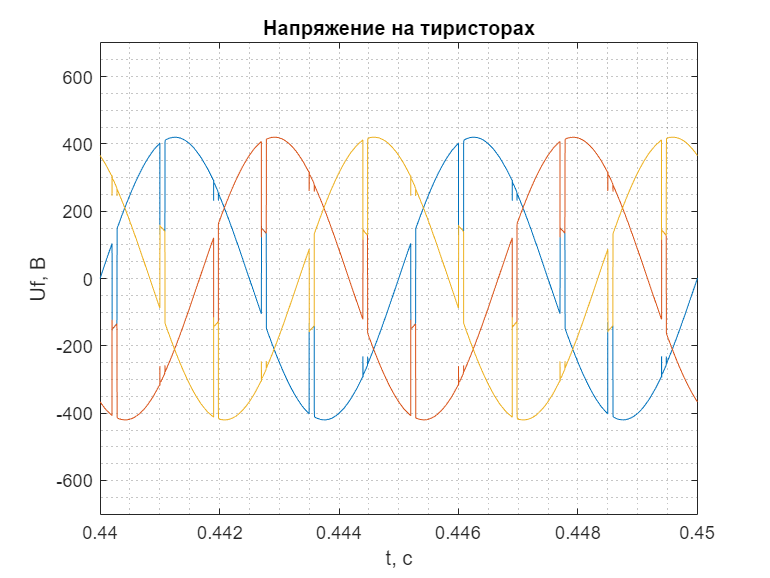

plot(ans.Scope2{1}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Uf, В');
    title('Напряжение на тиристорах');
    xlim([x.min x.max]);
    ylim([-700 700]);

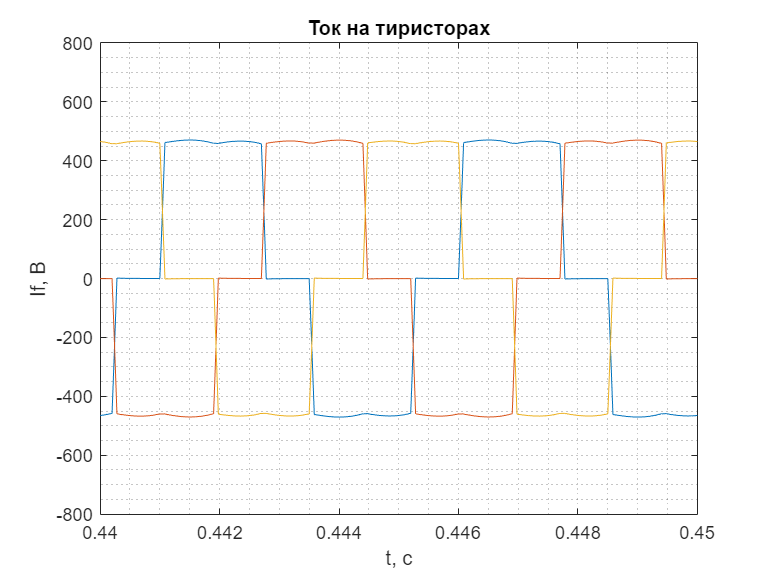

plot(ans.Scope2{2}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('If, В');
    title('Ток на тиристорах');
    xlim([x.min x.max]);
    ylim([-800 800]);

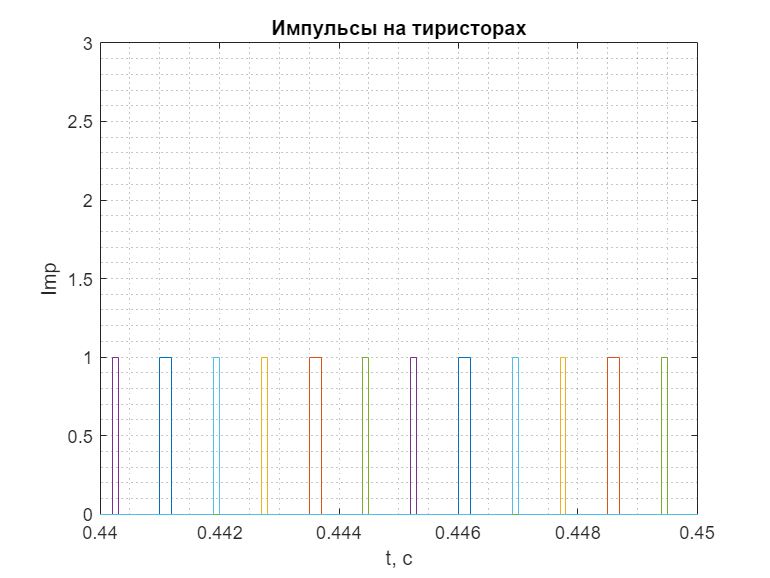

plot(ans.Scope2{3}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Imp');
    title('Импульсы на тиристорах');
    xlim([x.min x.max]);
    ylim([0 3]);

Диаграммы блока Scope 3:

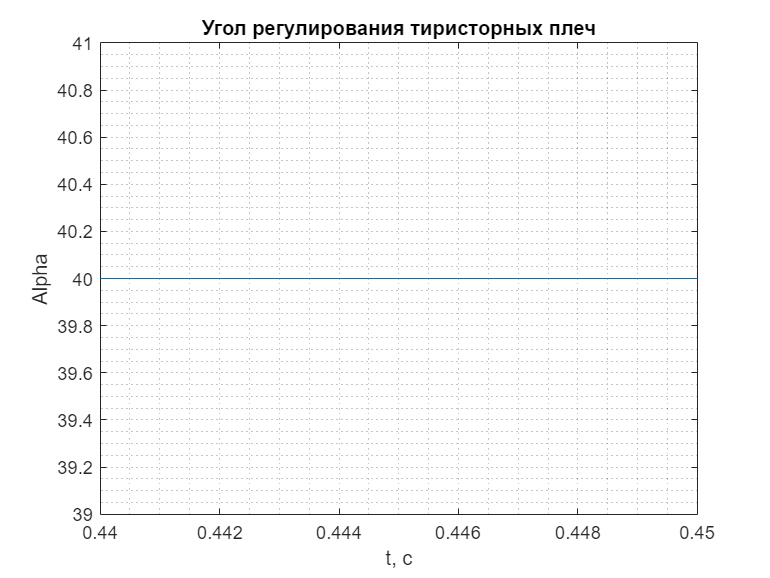

plot(ans.Scope3{1}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Alpha');
    title('Угол регулирования тиристорных плеч');
    xlim([x.min x.max]);

plot(ans.Scope3{2}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Uf, В');
    title('Напряжение на тиристорах');
    xlim([x.min x.max]);
    ylim([-700 700]);

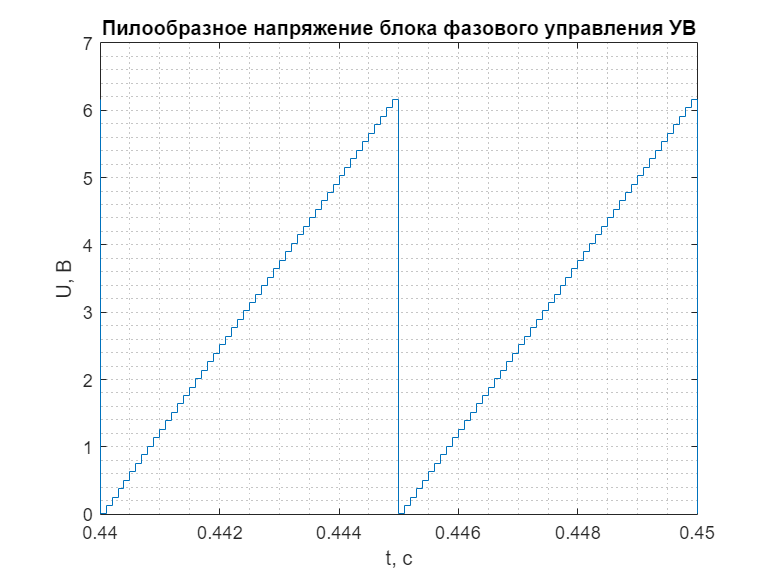

plot(ans.Scope3{3}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('U, В');
    title('Пилообразное напряжение блока фазового управления УВ');
    xlim([x.min x.max]);

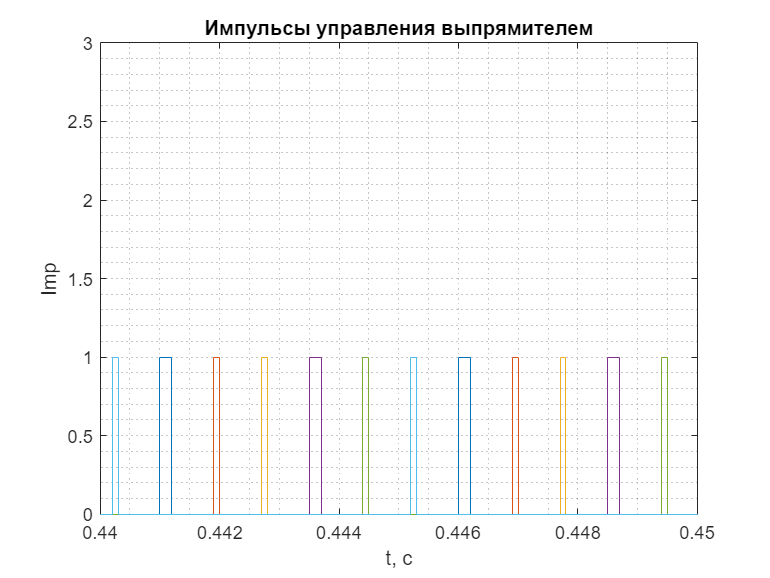

plot(ans.Scope3{4}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Imp');
    title('Импульсы управления выпрямителем');
    xlim([x.min x.max]);
    ylim([0 3]);

**8.3. При угле альфа = 60 и сопротивлении нагрузки Rn = 1 Ом:**

Диаграммы блока Scope 1:

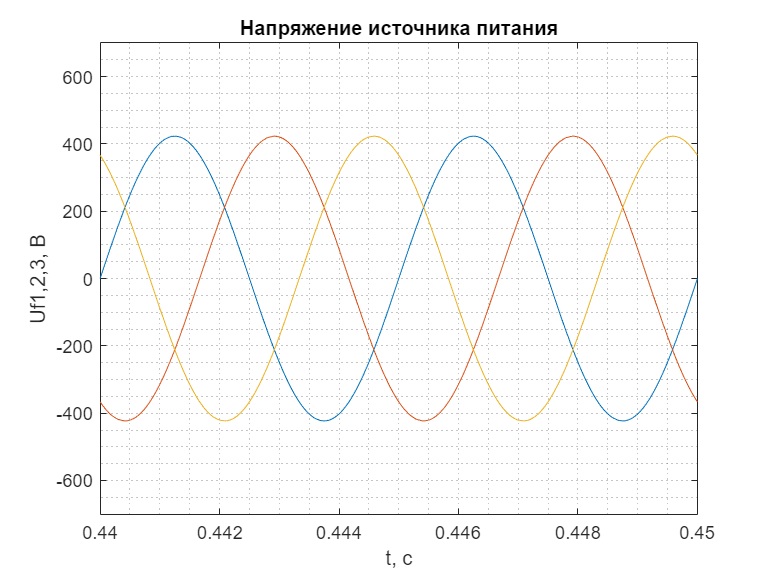

for a = 60
    Angle.Alpha = a;
    sim 'lab322.slx';
    RL.Res = 1;
    RL.Ind = RL.Res/ACsource.f_c;
end  
    plot(ans.Scope1{1}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Uf1,2,3, В');
    title('Напряжение источника питания');
    xlim([x.min x.max]);
    ylim([-700 700]);

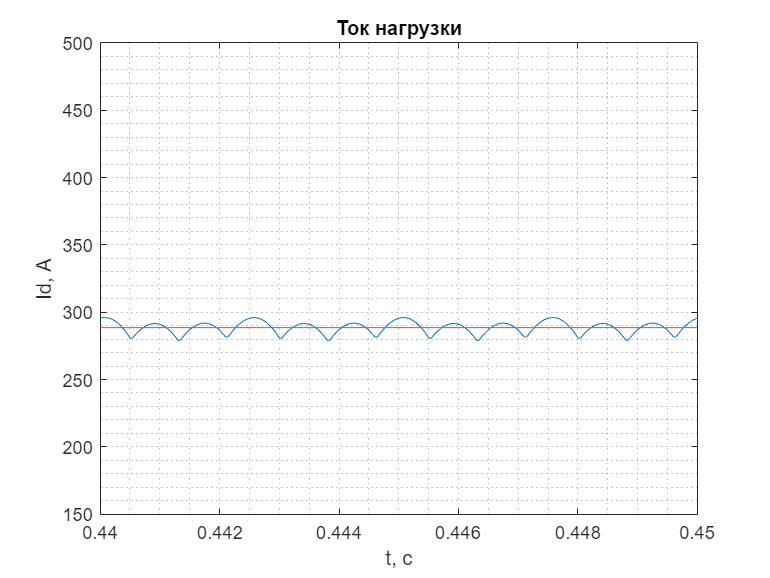

    plot(ans.Scope1{2}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Id, А');
    title('Ток нагрузки');
    xlim([x.min x.max]);
    ylim([150 500]);

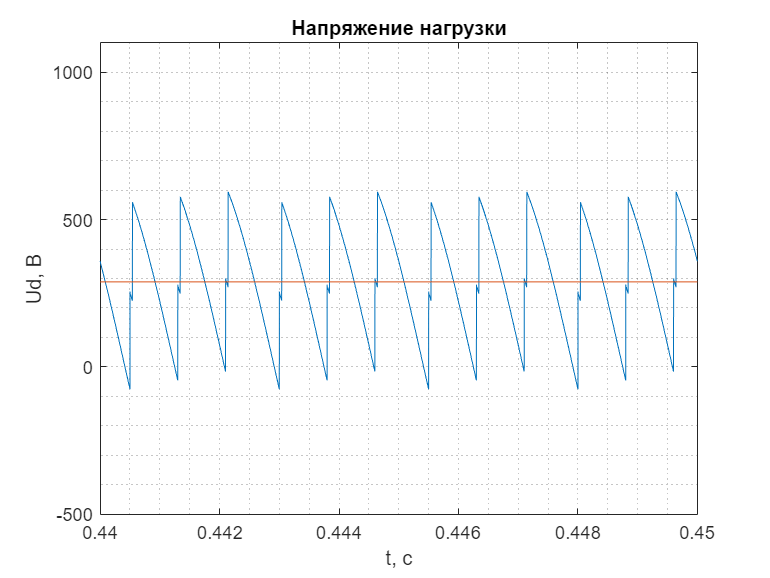

     plot(ans.Scope1{3}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Ud, В');
    title('Напряжение нагрузки');
    xlim([x.min x.max]);
    ylim([-500 1100]);

Диаграммы блока Scope 2:

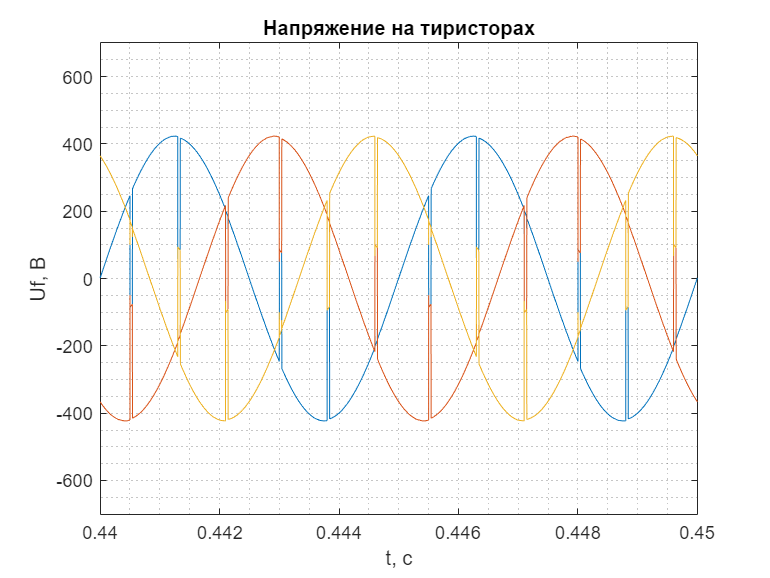

plot(ans.Scope2{1}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Uf, В');
    title('Напряжение на тиристорах');
    xlim([x.min x.max]);
    ylim([-700 700]);

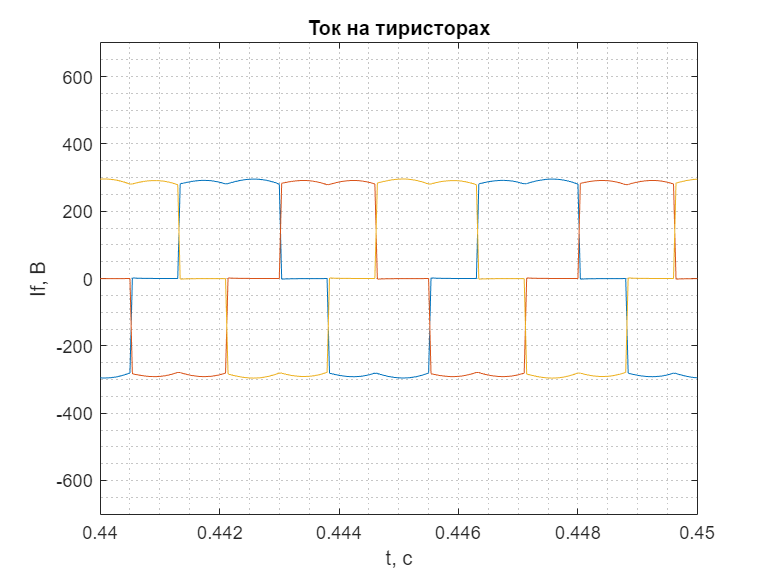

plot(ans.Scope2{2}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('If, В');
    title('Ток на тиристорах');
    xlim([x.min x.max]);
    ylim([-700 700]);

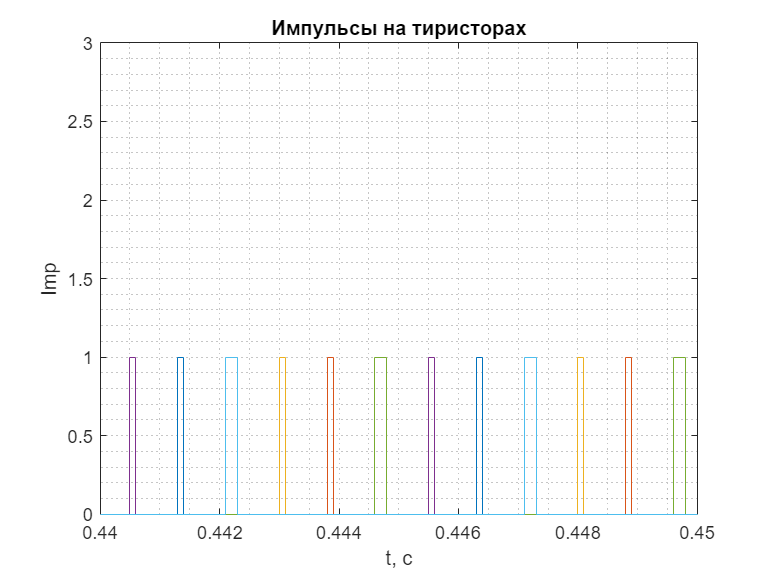

plot(ans.Scope2{3}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Imp');
    title('Импульсы на тиристорах');
    xlim([x.min x.max]);
    ylim([0 3]);

Диаграммы блока Scope 3:

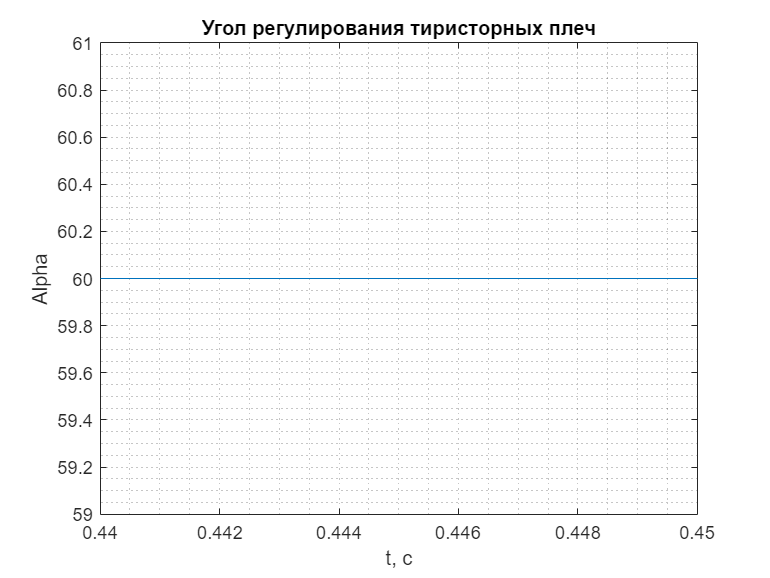

plot(ans.Scope3{1}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Alpha');
    title('Угол регулирования тиристорных плеч');
    xlim([x.min x.max]);

plot(ans.Scope3{2}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Uf, В');
    title('Напряжение на тиристорах');
    xlim([x.min x.max]);
    ylim([-700 700]);

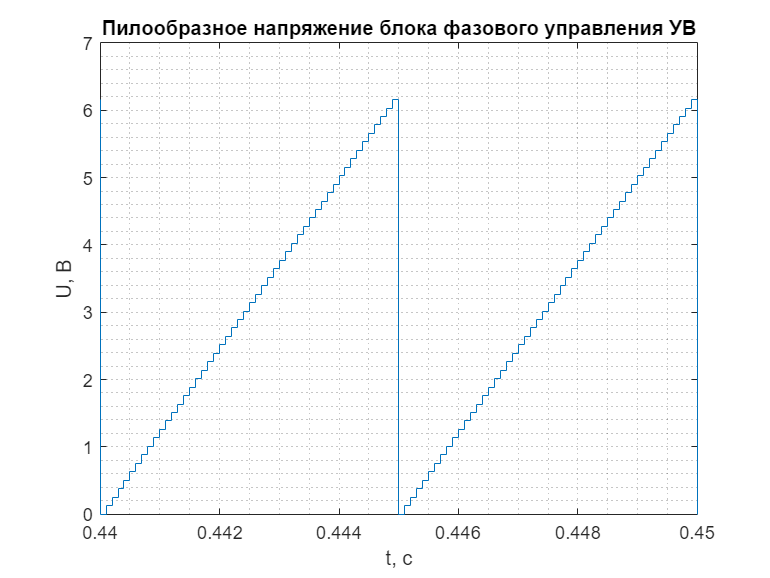

plot(ans.Scope3{3}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('U, В');
    title('Пилообразное напряжение блока фазового управления УВ');
    xlim([x.min x.max]);

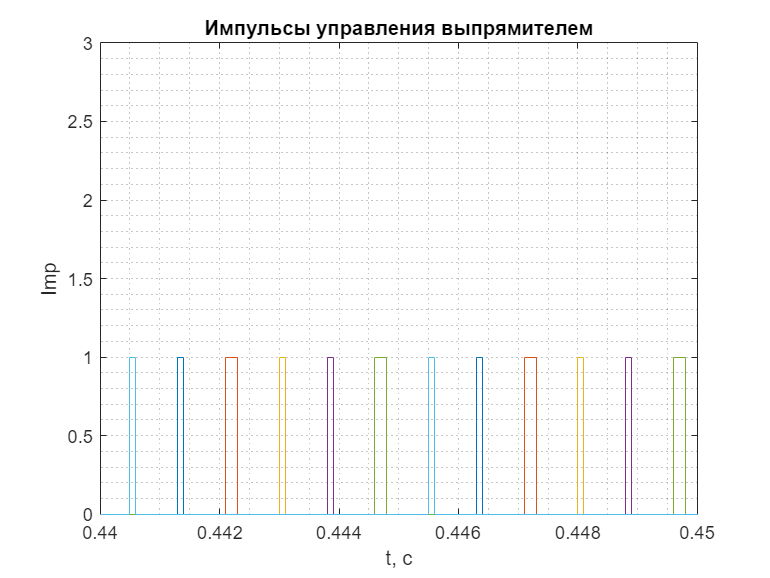

plot(ans.Scope3{4}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Imp');
    title('Импульсы управления выпрямителем');
    xlim([x.min x.max]);
    ylim([0 3]);

**9. Запись полученных данных в текстовый документ:**

Производим запись полученных в ходе выполнения лаборатоной работы таблиц: характеристик трехфазного двухполупериодного (мостового) управляемого выпрямителя и исследования регулировочной характеристики управляемого трехфазного выпрямителя соответственно:

writetable(T1,'Полученные в ходе расчета данные ЛР3.txt','WriteVariableNames',true,'Delimiter','tab');
type 'Полученные в ходе расчета данные ЛР3.txt';

U_a, В.	f_c, Гц.	Alpha, град.	R_n, Ом.	L_n, Гн.	I_n, А.	U_n, В.	I_1max, А.	Phi_1, град.	I_VT1sr, А.	I_VT1d, А.	I_VT1max, А.	U_VT1max, В.	S_1, кВА.	P_t, Вт.	P_1, кВт.	P_n, кВт.
423	200	0	1	0.015	637.25	637.25	699.14	-20.18	213.31	628.94	213.31	400.02	443.6	1244.91	8951.35	406.09
423	200	0	2	0.03	334.46	668.93	370.19	-14.89	112.38	646.28	112.38	417.35	234.9	1179.05	3498.53	223.73
423	200	0	4	0.06	170.12	680.49	188.74	-11.71	57.56	649.96	57.56	420.69	119.8	1125.2	1402.7	115.77
423	200	0	10	0.15	69	689.98	75.04	-6.89	22.62	653	22.62	422.6	47.6	1093.18	327.93	47.61
423	200	40	1	0.015	464.35	464.35	517.41	-46.19	157.77	560.63	157.77	388.22	328.3	975.08	15164.49	215.63
423	200	40	2	0.03	240.06	480.12	267.51	-44.67	81.62	577.29	81.62	399.86	169.7	931.11	7581.88	115.26
423	200	40	4	0.06	122.1	488.4	135.99	-43.77	41.54	584.9	41.54	405.72	86.3	905.11	3776.95	59.63
423	200	40	10	0.15	49.35	493.51	54.85	-42.95	16.8	589.26	16.8	409.34	34.8	888.22	1494.68	24.36
423	200	60	1	0.015	288.25	288.25	321.45

writetable(T2,'Полученные в ходе расчета данные ЛР3.txt','WriteMode','Append','Delimiter','\t','WriteVariableNames',true);
type 'Полученные в ходе расчета данные ЛР3.txt';

U_a, В.	f_c, Гц.	Alpha, град.	R_n, Ом.	L_n, Гн.	I_n, А.	U_n, В.	I_1max, А.	Phi_1, град.	I_VT1sr, А.	I_VT1d, А.	I_VT1max, А.	U_VT1max, В.	S_1, кВА.	P_t, Вт.	P_1, кВт.	P_n, кВт.
423	200	0	1	0.015	637.25	637.25	699.14	-20.18	213.31	628.94	213.31	400.02	443.6	1244.91	8951.35	406.09
423	200	0	2	0.03	334.46	668.93	370.19	-14.89	112.38	646.28	112.38	417.35	234.9	1179.05	3498.53	223.73
423	200	0	4	0.06	170.12	680.49	188.74	-11.71	57.56	649.96	57.56	420.69	119.8	1125.2	1402.7	115.77
423	200	0	10	0.15	69	689.98	75.04	-6.89	22.62	653	22.62	422.6	47.6	1093.18	327.93	47.61
423	200	40	1	0.015	464.35	464.35	517.41	-46.19	157.77	560.63	157.77	388.22	328.3	975.08	15164.49	215.63
423	200	40	2	0.03	240.06	480.12	267.51	-44.67	81.62	577.29	81.62	399.86	169.7	931.11	7581.88	115.26
423	200	40	4	0.06	122.1	488.4	135.99	-43.77	41.54	584.9	41.54	405.72	86.3	905.11	3776.95	59.63
423	200	40	10	0.15	49.35	493.51	54.85	-42.95	16.8	589.26	16.8	409.34	34.8	888.22	1494.68	24.36
423	200	60	1	0.015	288.25	288.25	321.45

  open 'Полученные в ходе расчета данные ЛР3.txt'  

**Вывод:**

В ходе лабораторной работы мы исследовали работу трехфазного мостового управляемого выпрямителя при работе на активно-индуктивную нагрузку. 

При увеличении сопротивления на нагрузке: 

1) Ток нагрузки уменьшается, а напряжение нагрузки увеличивается; 

2) Полная и активная мощности уменьшаются. Также уменьшаются потери на тиристорах и мощность на нагрузке; 

3) Угол 𝜑 увеличивается; 

4) Ток на тиристорах уменьшается; 

5) Максимальное напряжение на тиристорах увеличивается незначительно. 

При увеличении угла α: 

1) Ток нагрузки и напряжение уменьшается; 

2) Полная и активная мощности уменьшаются. Также уменьшаются потери на тиристорах и мощность на нагрузке; 

3) Угол 𝜑увеличивается; 

4) Ток на тиристорах уменьшается; 

5) Максимальное напряжение на тиристорах увеличивается незначительно.